# Presentation: Image enhancement and de-noising approach.

## INTRODUCTION

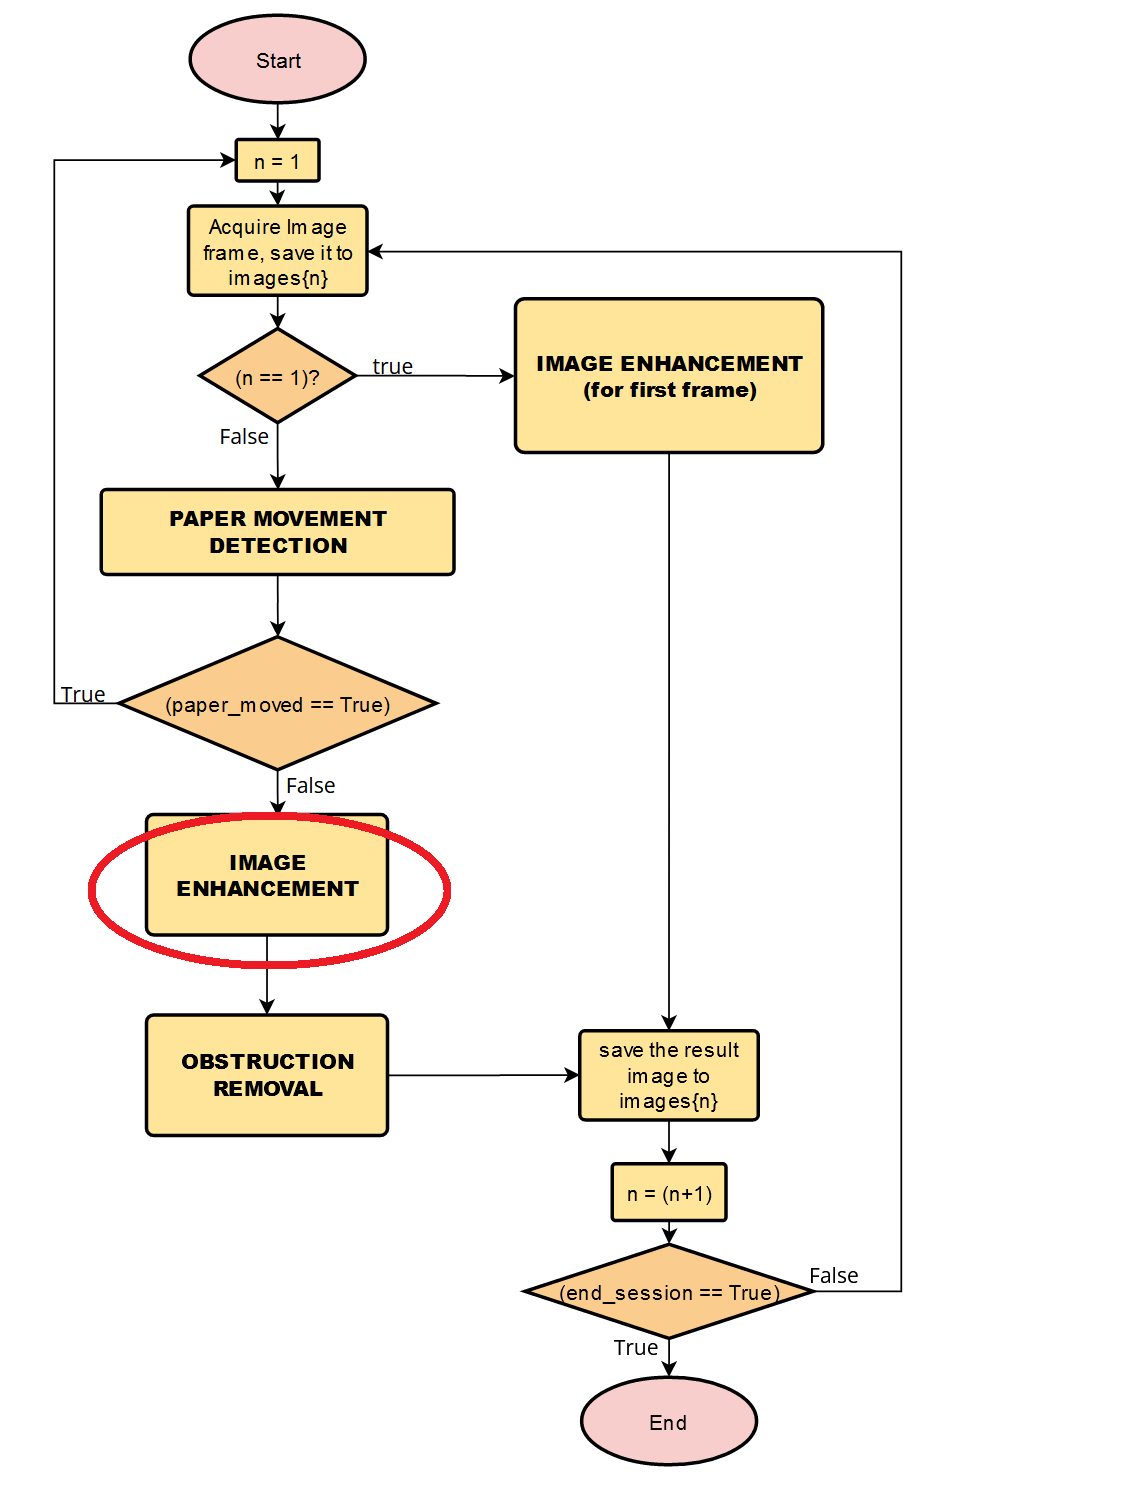

### Proposed output of the "IMAGE ENHANCEMENT" step:

The output Image should match these characteristics:

- The image should be truncated to show at maximum the enhanced white paper,

- The penstrokes on the image should be enhanced, with an increased saturation,

- The first frame will undergo its unique enhancement process so as to be transformed into a white frame and be a good reference to the next frames.

## METHODOLOGY ILLUSTRATION

The flow chart below shows basic information on the algorithm used in this presentation for the process of image enhancement.

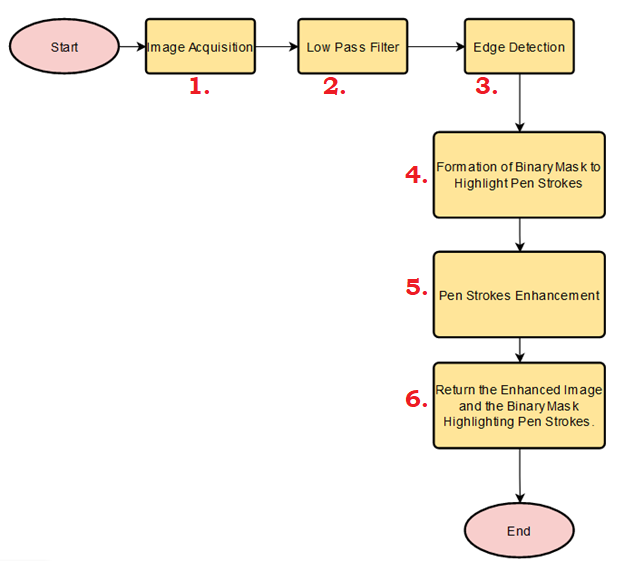

global enhancement_multiplier; 
enhancement_multiplier=2.75;
global LP_filter_PS N_smoothing Erosion_se N_erosion Dilution_se N_dilution

### STEP 1: IMAGE ACQUISITION

At this step, the program will read the input image and trim it so as to get at maximum the part that shows the white paper.

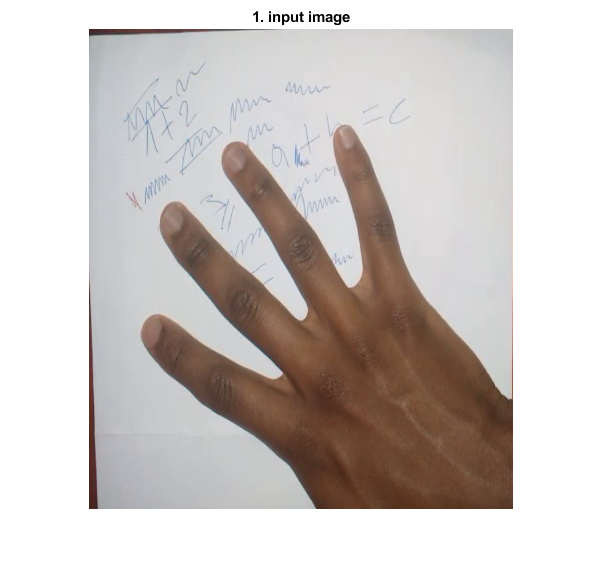


inputIm=imread("theImageWithHand.png");
[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.5);
imshow(inputIm)
title('1. input image')

[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.1);

total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
theRowPeriod = ceil((0.5/100) * total_numberOfRows);
theColPeriod = ceil((0.5/100) * total_numberOfColumns);
LP_filter_PS = (1/(theColPeriod*theRowPeriod)) * ones(theRowPeriod,theColPeriod);
N_smoothing = 1;

theRowPeriod = ceil((0.3/100) * total_numberOfRows);
theColPeriod = ceil((0.3/100) * total_numberOfColumns);
Erosion_se = ones(theRowPeriod,theColPeriod);
Dilution_se = ones(theRowPeriod,theColPeriod);
N_erosion = 1;
N_dilution = 1;


### STEP 2: LOW PASS FILTERING

This process will use a low pass filter to filter out noises in the image after converting it to grayscale.

inputIm_Smoothed=inputIm;
inputIm_Smoothed = imfilter(inputIm_Smoothed,LP_filter_PS);
imshow(inputIm_Smoothed);

inputIm_Smoothed_Gray=rgb2gray(inputIm_Smoothed);
imshow(inputIm_Smoothed_Gray)
title('2. input image smoothed')

### STEP 3: EDGE DETECTION

This step will use the 3x3 gaussian filter to detect edges in the image, then threshold the output so as to highlight areas where the ink has traced.

F=[0 1 0; 1 -4 1; 0 1 0] ;

inputIm_Edges=imfilter(inputIm_Smoothed_Gray,F);
inputIm_Edges = histeq(inputIm_Edges);
inputIm_MaskForPenStrokes = (inputIm_Edges < 250);
imshow(inputIm_MaskForPenStrokes)
title('3. Detected Edges')

### STEP 4: FORMATION OF BINARY MASK TO HIGHLIGHT PENSTROKES

This step will erode the binary image, so as to enhance the highlights of penstrokes. It will also do a dilution so as to remove remaining noises. (This is an Opening process)

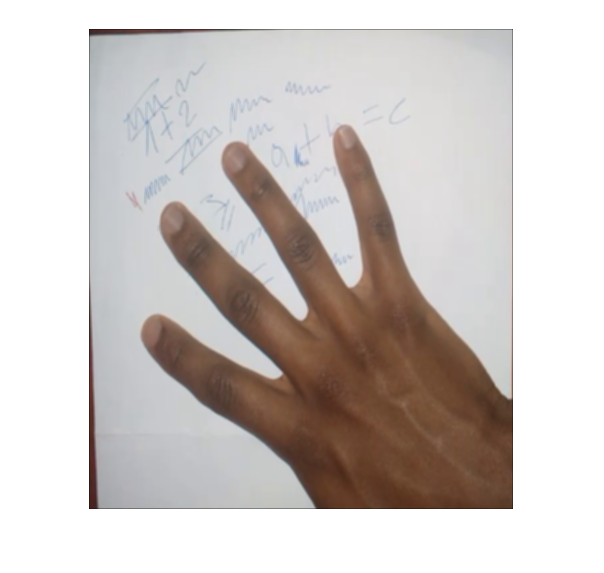

pattern = Erosion_se;

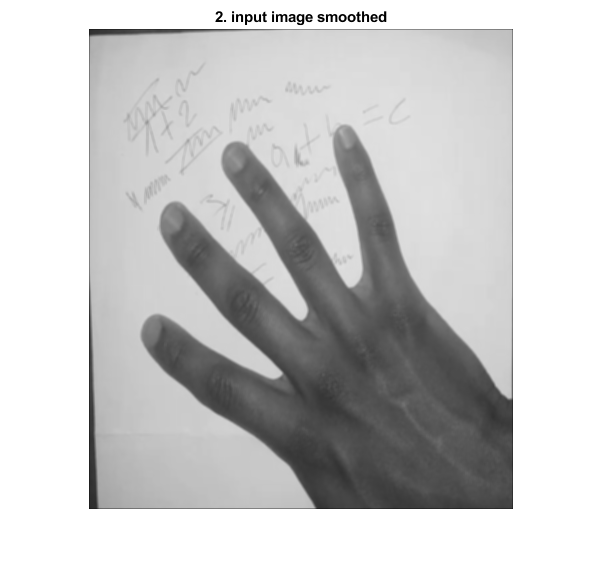

% pattern = ones(3);
for t=1:1:N_erosion
    inputIm_MaskForPenStrokes=imerode(inputIm_MaskForPenStrokes,pattern);
end

pattern = Dilution_se;
% pattern = ones(1,2);
for t=1:1:N_dilution
    inputIm_MaskForPenStrokes=imdilate(inputIm_MaskForPenStrokes,pattern);
end

imshow(inputIm_MaskForPenStrokes)
title('4. Binary Mask, highlighting pen strokes, excluding noises')

### STEP 5: PENSTROKES ENHANCEMENT

This process will do an element-wise multiplication between the input image and the created mask (complemented), then increase the saturation of the pen strokes.

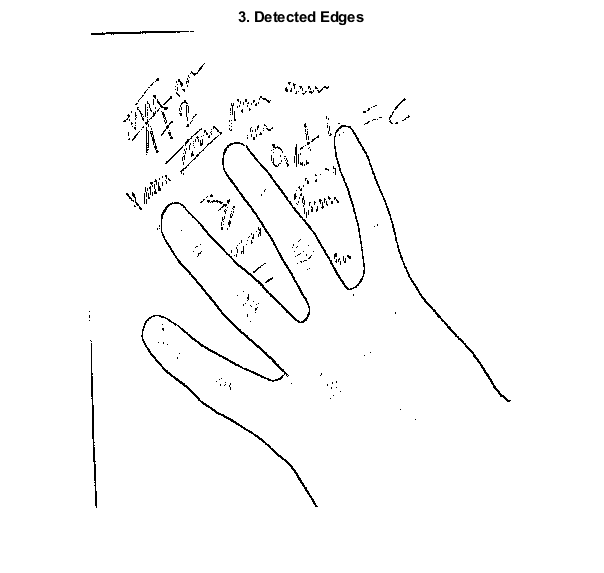


inputIm_MaskForPenStrokes = uint8(inputIm_MaskForPenStrokes);

inputIm_WhiteArea= inputIm_MaskForPenStrokes.*inputIm * enhancement_multiplier;
% inimWHITE= inputMask * 255 ;

inputIm = uint8(~inputIm_MaskForPenStrokes) .* inputIm;

inputIMAGE_HSV=rgb2hsv(inputIm);
inputIMAGE_HSV(:,:,2)=inputIMAGE_HSV(:,:,2)*10;
inputIm=hsv2rgb(inputIMAGE_HSV);

imshow(uint8(inputIm*255));
title('5. Pen Strokes Enhanced')


### STEP 6: RETURNING THE ENHANCED IMAGE AND THE BINARY MASK

This process will set the remaining part (the part which does not represent penstrokes) into pure white, then adds it to the part that represents penstrokes. After that, it will return the enhanced image and a binary mask to be later used in obstruction removal process, so as to protect pen strokes from being considered as obstruction (see the next topic: Obstruction Removal)

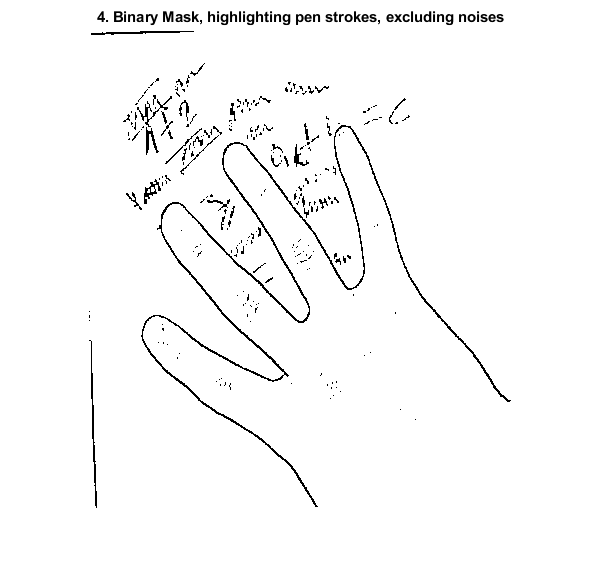

outputIMAGE= uint8(inputIm_WhiteArea) + uint8(inputIm*255);
outputImage3 = outputIMAGE;

imshow(outputIMAGE)
title('6.a. Enhanced Image')

global mypenstroke_mask
mypenstroke_mask = ~inputIm_MaskForPenStrokes;
imshow(mypenstroke_mask)
title('6.b. Pen Strokes Mask (to be used in the next phase: OBSTRUCTION REMOVAL)')


For the current image, image enhancement worked better than the previous case (the case we discussed on weeks ago). But it can also be seen that lack of illumination correction impacted much on the results of the output, as it contains few noises. One of our next challenge to tackle with is illumination correction.

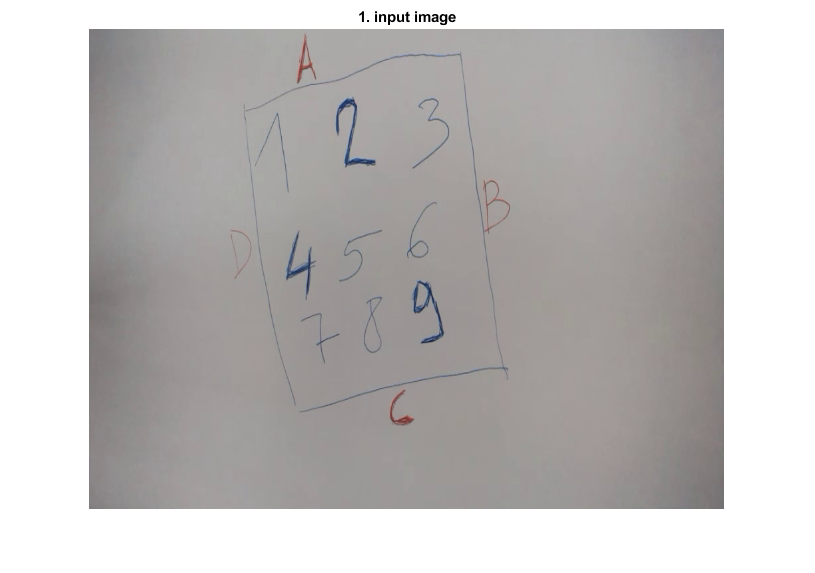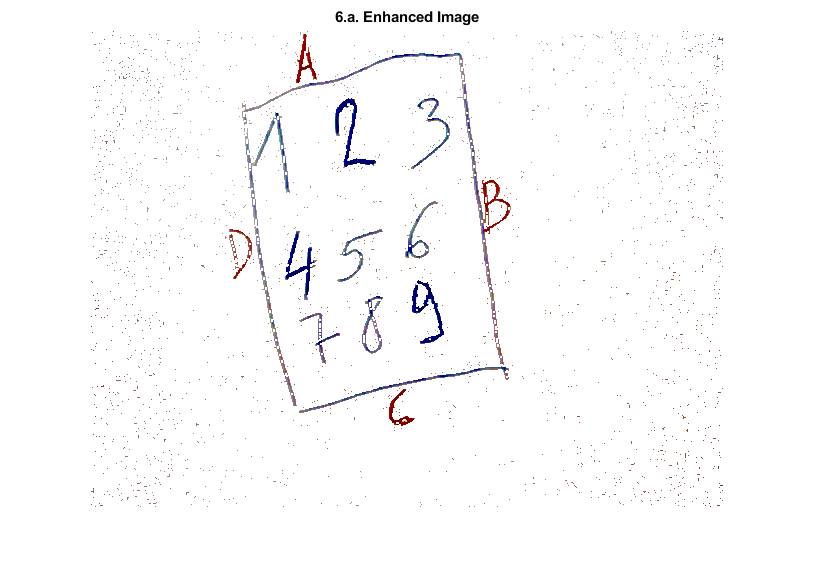

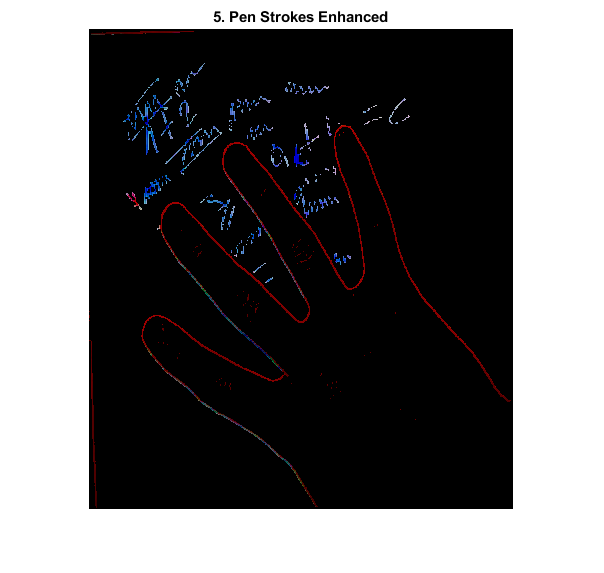

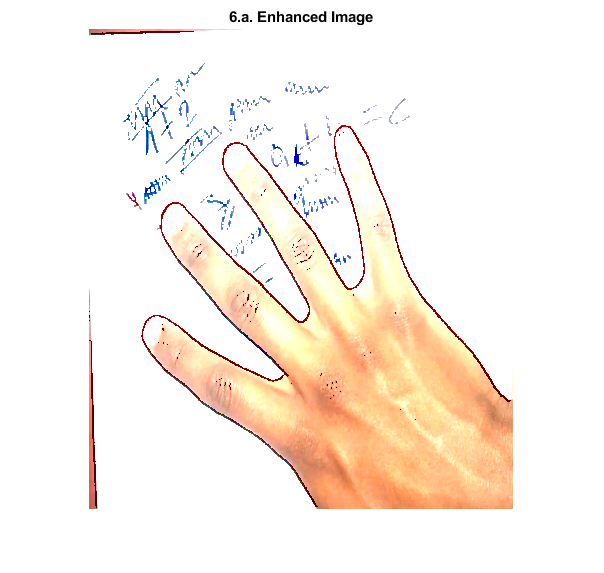

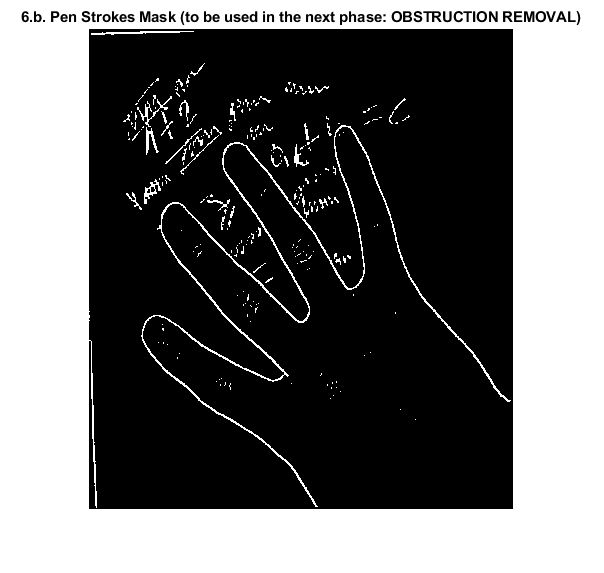

clc